# Nonlinear standing wave on a semi-infinite lasso graph

First, set up the folder to house the solutions and the quantum graph.

tag='lasso';
Phi=quantumGraphFromTemplate(tag,'LVec',[2*pi inf]);%,'Discretization','Chebyshev','nX',64);
dataDir = makeContinuationDirectory(Phi,tag);

Created directory data/lasso/041.


Set up the functions needed for the nonlinear solver and continuation program using the default value $f(z)=2z^3$

saveNLSFunctionsGraph(dataDir,Phi);

Solve the nonlinear standing wave equation from an initial guess with a bump on edge $\mathtt{e}_2$.

edges=1;
signs=1;
Lambda0=-1;
filenumber=saveHighFrequencyStandingWave(dataDir,Lambda0,edges,signs);

File saved to data/lasso/041/savedFunction.001.
File number is 1. 


Now, the solution is stored as file `savedFunction.001`

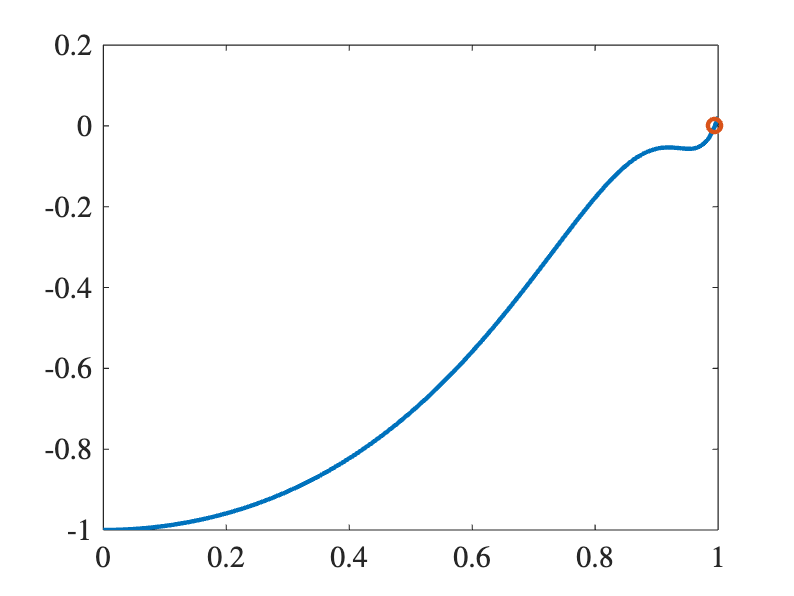

vec = load(fullfile(dataDir,"savedFunction.001"));
vec2 = lassoExactStanding(Phi,Lambda0,1,'dn1');

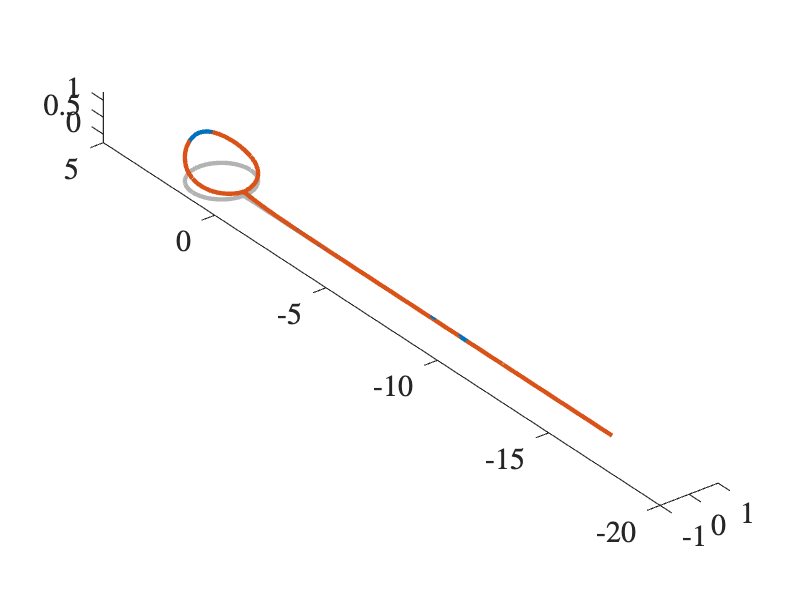

Phi.plot(vec);
hold on
Phi.plot(vec2,'red');

options=continuerSet([],'LambdaThresh',-3,'NThresh',9,'plotFlag',false,'minNormDelta',1e-3);

direction=-1;
branch1=continueFromSaved(dataDir,filenumber,direction,options);

Lambda threshold -3.0 crossed.
Branch number 1.
Data saved to directory data/lasso/040/branch001.
No branching bifurcations found.


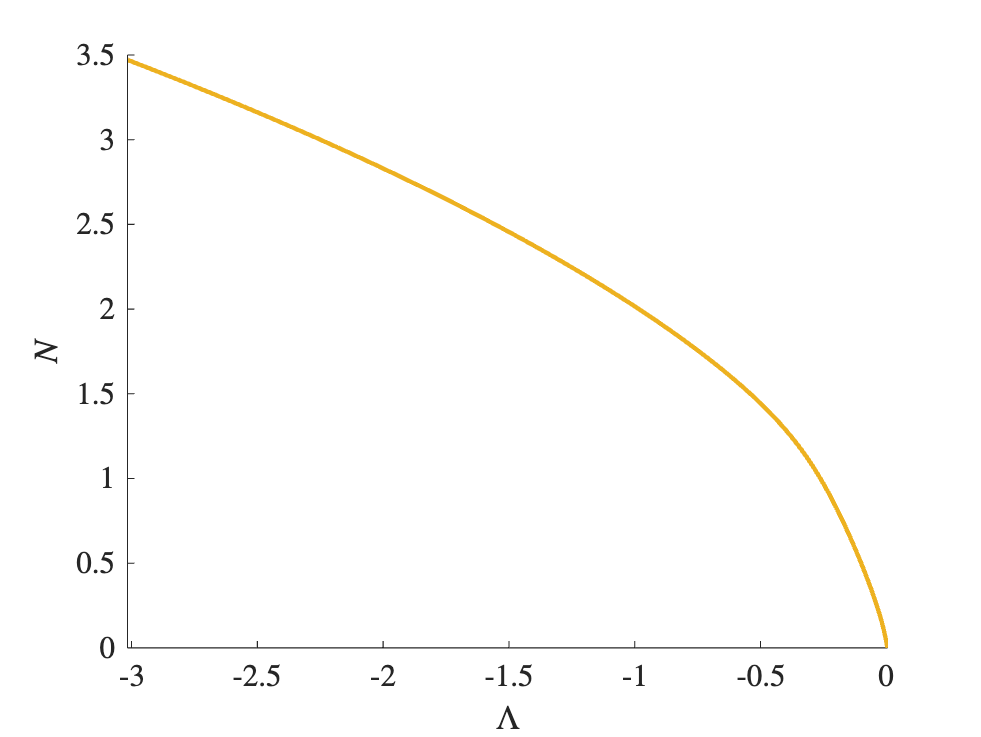

bifurcationDiagram(dataDir)

nToPlot=16;
nDoubles=0;
saveEigenfunctions(Phi,tag,dataDir,nToPlot,nDoubles);

branch2=continueFromEig(dataDir,13,options);

N threshold 9.0 crossed.
Branch number 2.
Data saved to directory data/lasso/040/branch002.
No branching bifurcations found.


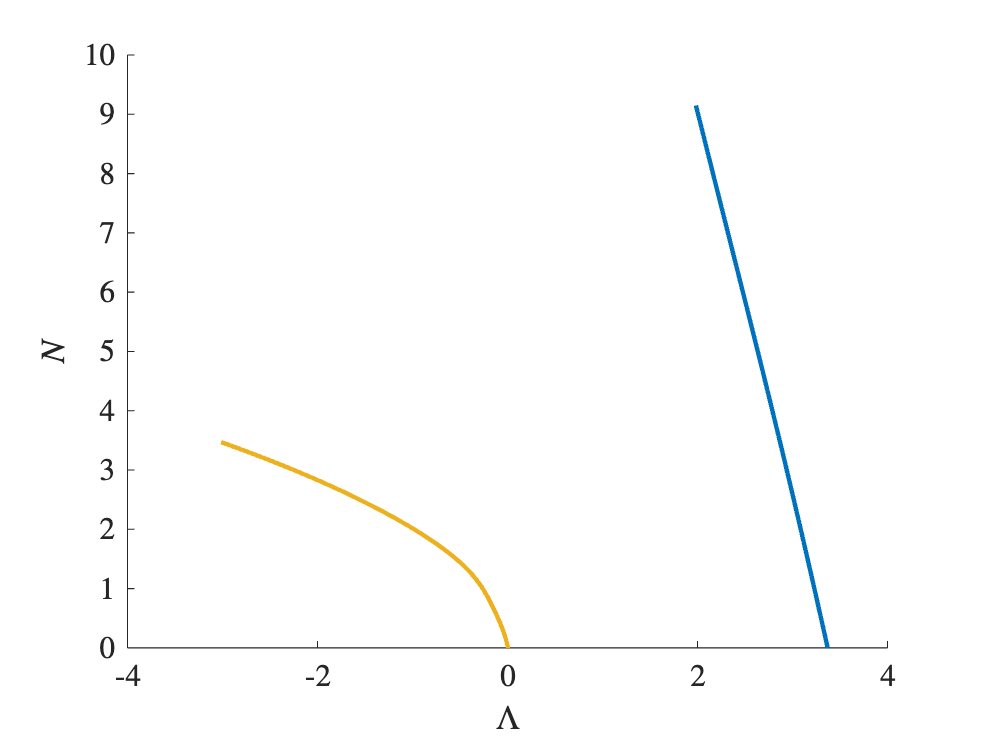

bifurcationDiagram(dataDir)

location=5;
direction=1;
branch3=continueFromBranchPoint(dataDir,branch2,location,direction,options);

Index exceeds the number of array elements. Index must not exceed 0.

Error in getFirstSolutionFromBranchpoint (line 12)
pointNumber=bifurcationLocations(bifNumber);

Error in continueFromBranchPoint (line 13)
    getFirstSolutionFromBranchpoint(dataDir,oldB

bifurcationDiagram(dataDir)